# General Terramechanics Trade Study

### Experiment parameters


$$b = \text{wheel width}$$



$$D = \text{wheel diameter}$$



$$N_{tot} = \text{total number of grousers}$$



$$s = \text{wheel slip ratio}$$



$$h = \text{grouser height}$$



$$N_{w} = \text{number of wheels}$$



$$\theta_{slope} = \text{slope angle}$$


syms b D N_tot s h N_w theta_s

### Lunar Soil Parameters


$$k_c = \text{modulus of cohesion of soil deformation}$$



$$k_{\phi} = \text{modulus of friction of soil deformation}$$



$$n = \text{soil heuristic parameter}$$



$$\phi = \text{angle of internal resistance of soil}$$



$$\gamma = \text{density of soil}$$



$$c = \text{soil cohesion}$$



$$K_{shear} = \text{shear deformation modulus}$$


k_c = 1400; % N/m^2
k_phi = 820000; % N/m^3
n = 1;
phi = 0.6109;
gamma = 2472; % N/m³
c = 170; % N/m^2
K_shear = .0178; % m

### Known values


$$m_a = \text{mass of astronaut}$$



$$m_p = \text{mass of payload}$$



$$m_v = \text{mass of vehicle}$$



$$g = \text{lunar gravitational constant}$$


m_a = 170; % kg
m_p = 80; % kg
m_v = 250 % kg

m_v = 250


m_tot = 2*m_a + m_p + m_v;

g = 1.62; % m/s^2

### Compression Resistance 


$$R_c = \left(\frac{k_c+bk_\phi}{n+1}\right) z^{n+1}$$


    
$$z = \text{compression depth}$$


    
$$z = \left(\frac{3}{3-n}\frac{W_w}{(k_c+bk_\phi)\sqrt{D}}\right)^{\frac{2}{2n+1}}$$


    
$$W_w = \text{weight on wheel}$$


    
$$W_w = \frac{m_{tot} g}{N_w}$$


     assume weight is evenly distributed between wheels

W_w = (g*(m_tot))/N_w;

z = ((3/(3-n))*(W_w/((k_c+b*k_phi)*sqrt(D))))^(2/(2*n+1));

R_c = (k_c+b*k_phi)/(n+1) * z^(n+1);

### Bulldozing Resistance


$$R_b = \frac{b\sin(\alpha+\phi)}{2\sin\alpha\cos\phi}(2zcK_c+\gamma z^2K_\gamma) + \frac{l^3_o \, \gamma}{3}\left(\frac{\pi}{2}-\phi\right) + cl^2_o\left[1+\tan\left(\frac{\pi}{4}+ \frac{\phi}{2}\right)\right]$$


    
$$\alpha = \text{angle of attack of wheel in soil} = \cos^{-1} \left(1-\frac{2z}{D} \right)$$


    
$$K_c = \text{Cohesive modulus of soil deformation} = (N_c - \tan\phi)\cos^2\phi$$


        
$$N_q = \frac{\exp \left[\left(\frac{3\pi}{2}-\phi \right)\tan\phi \right]}{2\cos^2 \left(\frac{\pi}{4} + \frac{\phi}{2} \right)} $$


        
$$N_c = \frac{N_q -1}{\tan\phi}$$


    
$$K_\gamma = \left[ \frac{2N_\gamma}{\tan\phi} + 1\right] \cos^2\phi$$


        
$$N_\gamma = \frac{2(N_q+1)\tan\phi}{1+0.4\sin(4\phi)}$$


    
$$l_o = z\tan^2 \left( \frac{\pi}{4} - \frac{\phi}{2} \right)$$


alpha = acos(1-((2*z)/D));

N_q = exp(((3*pi)/2 - phi)*tan(phi))/(2*cos(pi/4 + phi/2)^2);
N_c = (N_q-1)/tan(phi);
K_c = (N_c - tan(phi))*cos(phi)^2;
N_gamma = (2*(N_q+1)*tan(phi))/(1+0.4*sin(4*phi));
K_gamma = (2*N_gamma/tan(phi) + 1)*cos(phi)^2;

l_o = z*tan((pi/4)-(phi/2))^2;

R_b = ((b*sin(alpha+phi))/(2*sin(alpha)*cos(phi)))*(2*z*c*K_c+gamma*z^2*K_gamma)+...
    ((l_o^3*gamma)/3)*((pi/2)-phi)+c*l_o^2*(1+tan((pi/4)+(phi/2)));

### Gravitation Resistance


$$R_g = W_v \sin\theta_{slope}
$$


        
$$W_{tot} = \text{total weight}$$


W_tot = g*(m_tot);
R_g = W_tot * sind(theta_s);

### **Rolling Resistance**


$$R_r = W_{tot} \, c_f
$$


    
$$c_f  (\text{coefficient of friction}) = 0.05$$


c_f = 0.05;
R_r = W_tot*c_f;

### Tractive force for smooth wheel

 
$$H = (blc_0+W_w\tan\phi)\left[1-\frac{K}{sl} \left(1-e^{\frac{-sl}{K}}\right) \right]$$


     
$$l = \text{length of contact patch} = \frac{D}{2}\cos^{-1} \left(1-\frac{2z}{D}\right)$$


l = (D/2)*acos(1-((2*z)/D));

H_s = (b*l*c+W_w*tan(phi))*(1-(K_shear/(s*l))*(1-exp((-s*l)/K_shear)));

### Tractive Force for wheels with grousers


$$H = \left[blc_0 \left(1+ \frac{2h}{b} \right)N_g + W_w \tan\phi \left(1+0.64\frac{h}{b} \: \tan^{-1} \frac{b}{h} \right) \right] \left[1-\frac{K_{shear}}{sl} \left(1-e^{\frac{-sl}{K_{shear}}} \right) \right]$$


    
$$N_g = \frac{\pi D}{N_{tot}l}$$


N_g = (pi*D)/(N_tot*l);
H_g = (b*l*c*(1+((2*h)/b)*N_g + W_w*tan(phi)*(1+0.64*(h/b)*atan(b/h))))*(1-(K_shear/(s*l))*(1-exp((-s*l)/K_shear)));

### **Drawbar pull**


$$DP =N_w H - (N_wR_c + N_wR_b + R_g + R_r)$$


R_sum = (N_w*R_c + N_w*R_b + R_g + R_r);

### Value selection

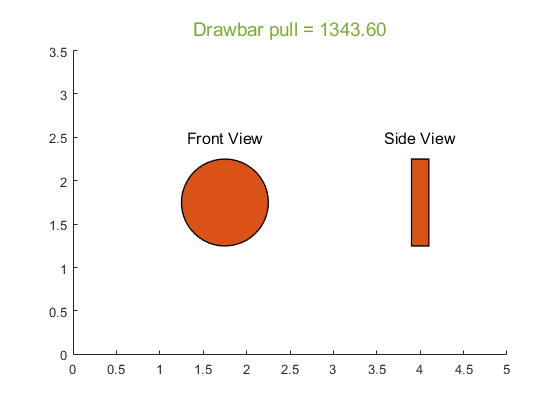

b_ =20* .01;
D_ = 100 * .01;
N_w_ = 4 ;

s_ = 0.3 ;
theta_s_ = 15 ;

grousers = true;

N_tot_ = 20 ;
h_ = 1 * .01;


if grousers
    H = H_g;
else
    H = H_s;
end

DP = N_w*H - R_sum;

figure
axis equal
xlim([0 5])
ylim([0 3.5])
r = D_/2;

rectangle('Position',[1.75-r,1.75-r,D_,D_],'FaceColor',[0.8500 0.3250 0.0980],...
    'EdgeColor','k','LineWidth',1,'Curvature',[1 1])
rectangle('Position',[4-b_/2,1.75-r,b_,D_],'FaceColor',[0.8500 0.3250 0.0980],...
    'EdgeColor','k','LineWidth',1)
text(1.75,2+r,"Front View",'FontSize',12,'HorizontalAlignment',"center")
text(4,2+r,"Side View",'FontSize',12,'HorizontalAlignment',"center")
DP_ = double(subs(DP,[b D N_tot s h N_w theta_s],[b_ D_ N_tot_ s_ h_ N_w_ theta_s_]));

formatSpec = "Drawbar pull = %.2f";
str = sprintf(formatSpec,DP_);

if DP_ < 0
    text_color = '#A2142F';
else
    text_color = '#77AC30';
end
text(2.5,3.75,str,'FontSize',14,'HorizontalAlignment',"center","Color",text_color)